# Lista 4

### Przydatne polecenia:

`xlabel('text')` - etykieta osi $x$.

`ylabel('text')` - etykieta osi $y$.

`title('text')` - tytuł wykresu.

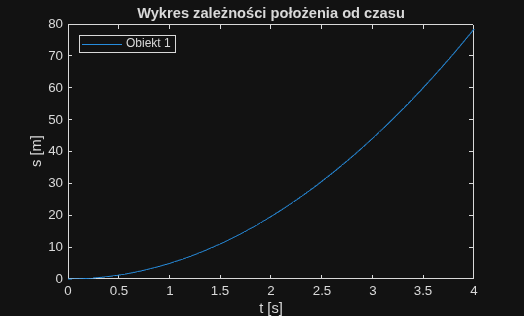

t = linspace(0,4,100);
plot(t, 1/2*9.8*t.^2)
xlabel('t [s]')
ylabel('s [m]')
title('Wykres zależności położenia od czasu')
legend('Obiekt 1','location', 'northwest')

**Zad. 1.** Suma ciągów geometrycznych $$1 + r + r^2 + r^3 + \ldots + r^n$$ zbliża się do granicy $ $\frac{1}{1-r}$$ dla $$|r|<1$$, gdy $$n\rightarrow \infty$$. Utwórz wektor $$n$$ składający się z 11 elementów od 0 do 10. Przyjmij $$r = 0.5$$ i utwórz kolejny wektor $$x = [r^0\: r^1\: r^2 \ldots r^n]$$ za pomocą polecenia `x=r.^n`. Następnie oblicz sumę elementów tego wektora stosując polecenie `s=sum(x)`. Oblicz granicę $$\frac{1}{1-r}$$ i porównaj z obliczoną sumą $$s$$. Powtórz tę procedurę przyjmując $$n$$ od 0 do 50, a następnie od 0 do 100.

format long
n = [0:10]

n =      0     1     2     3     4     5     6     7     8     9    10


r = 0.5

r =    0.500000000000000


x = r.^n

x =    1.000000000000000   0.500000000000000   0.250000000000000   0.125000000000000   0.062500000000000   0.031250000000000   0.015625000000000   0.007812500000000   0.003906250000000   0.001953125000000   0.000976562500000


sum(x)

ans =    1.999023437500000



n = [0:50]

n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


x = r.^n

x =    1.000000000000000   0.500000000000000   0.250000000000000   0.125000000000000   0.062500000000000   0.031250000000000   0.015625000000000   0.007812500000000   0.003906250000000   0.001953125000000   0.000976562500000   0.000488281250000   0.000244140625000   0.000122070312500   0.000061035156250   0.000030517578125   0.000015258789062   0.000007629394531   0.000003814697266   0.000001907348633   0.000000953674316   0.000000476837158   0.000000238418579   0.000000119209290   0.000000059604645   0.000000029802322   0.000000014901161   0.000000007450581   0.000000003725290   0.000000001862645   0.000000000931323   0.000000000465661   0.000000000232831   0.000000000116415   0.000000000058208   0.000000000029104   0.000000000014552   0.000000000007276   0.000000000003638   0.000000000001819   0.000000000000909   0.000000000000455   0.000000000000227   0.000000000000114   0.000000000000057   0.000000000000028   0.000000000000014   0.000000000000007   0.000000000000004   0.00000000000

sum(x)

ans =    1.999999999999999



n = [0:1000]

n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


x = r.^n

x =    1.000000000000000   0.500000000000000   0.250000000000000   0.125000000000000   0.062500000000000   0.031250000000000   0.015625000000000   0.007812500000000   0.003906250000000   0.001953125000000   0.000976562500000   0.000488281250000   0.000244140625000   0.000122070312500   0.000061035156250   0.000030517578125   0.000015258789062   0.000007629394531   0.000003814697266   0.000001907348633   0.000000953674316   0.000000476837158   0.000000238418579   0.000000119209290   0.000000059604645   0.000000029802322   0.000000014901161   0.000000007450581   0.000000003725290   0.000000001862645   0.000000000931323   0.000000000465661   0.000000000232831   0.000000000116415   0.000000000058208   0.000000000029104   0.000000000014552   0.000000000007276   0.000000000003638   0.000000000001819   0.000000000000909   0.000000000000455   0.000000000000227   0.000000000000114   0.000000000000057   0.000000000000028   0.000000000000014   0.000000000000007   0.000000000000004   0.00000000000

sum(x)

ans =      2



g=1/(1-r)

g =      2


**Zad. 2**. Sporządź wykresy $$y = \sin x$$ oraz $$y = \cos x$$ dla $$0\leq x \leq 2\pi$$ opierając go na 100 punktach rozmieszczonych liniowo w określonych odstępach. Opisz osie i zatytułuj ,,Wykres sporządzony przez \textit{imię nazwisko}''. Na drugim podwykresie narysuj te same krzywe zaznaczając punkty kółkami bez ich łączenia (`plot(x,y,'o')`)`.`

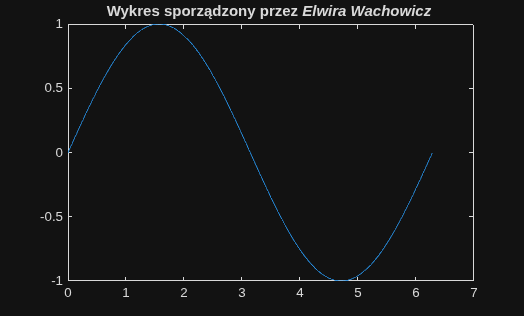

clf();
x = 0:0.01:2*pi;
plot(x,sin(x));
%%% Kursywa widoczna gdy otworzy się osobne okno z rysunkiem
title('Wykres sporządzony przez {\itElwira Wachowicz} ');

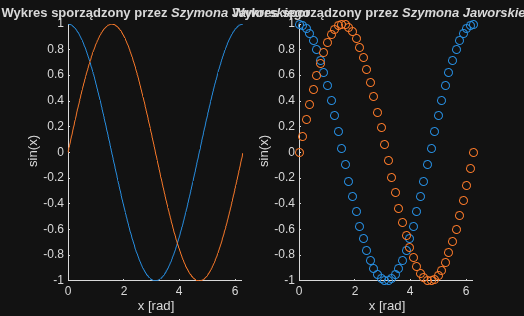


clf();

x1 = linspace(0,2*pi,50);

subplot(1,2,1);

hold on
plot(x1,cos(x1));
plot(x1,sin(x1));

xlabel("x [rad]");
ylabel("sin(x)");
title('Wykres sporządzony przez {\itSzymona Jaworskiego}')
hold off

subplot(1,2,2);
hold on

plot(x1,cos(x1),"o");
plot(x1,sin(x1),"o");

xlabel("x [rad]")
ylabel("sin(x)")
title('Wykres sporządzony przez {\itSzymona Jaworskiego}');

hold off

**Zad. 3.** Za pomocą polecenia `p``lot3(x,y,z)` wykreśl okrągłą sprężynę$ $x(t) = \sin(t)$, $y(t) = \cos(t)$, $z(t) = t$$, dla plot3(sin(t),cos(t),t)$$0 \leq t \leq 20$$. Opisz osie i zatytułuj wykres.

clf;
t = [0:0.1:20]

t =                    0   0.100000000000000   0.200000000000000   0.300000000000000   0.400000000000000   0.500000000000000   0.600000000000000   0.700000000000000   0.800000000000000   0.900000000000000   1.000000000000000   1.100000000000000   1.200000000000000   1.300000000000000   1.400000000000000   1.500000000000000   1.600000000000000   1.700000000000000   1.800000000000000   1.900000000000000   2.000000000000000   2.100000000000000   2.200000000000000   2.300000000000000   2.400000000000000   2.500000000000000   2.600000000000000   2.700000000000000   2.800000000000000   2.900000000000000   3.000000000000000   3.100000000000000   3.200000000000000   3.300000000000000   3.400000000000000   3.500000000000000   3.600000000000000   3.700000000000000   3.800000000000000   3.900000000000000   4.000000000000000   4.100000000000001   4.200000000000000   4.300000000000000   4.400000000000000   4.500000000000000   4.600000000000001   4.700000000000000   4.800000000000001   4.90000000000

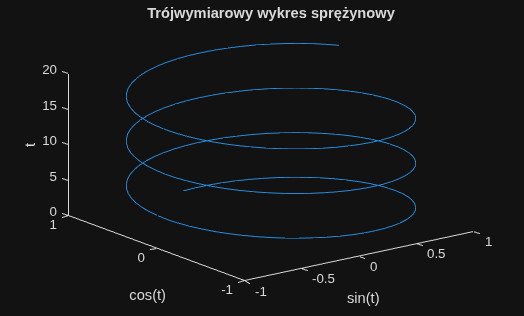

plot3(sin(t),cos(t),t)
hold on
title("Trójwymiarowy wykres sprężynowy")
xlabel("sin(t)")
ylabel("cos(t)")
zlabel("t")
hold off